# Bending Analysis

## Section 3.1 Validation Measures


% Import data
lab3data = xlsread("materialslab3.xlsx");
cant_load = lab3data(1:4,1); % grams
cant_al = lab3data(1:4,2);
cant_br = lab3data(1:4,3);
cant_st = lab3data(1:4,4);
tp_load = lab3data(1:4,5); % grams
tp_al_6 = lab3data(1:4,6);
tp_br_6 = lab3data(1:4,7);
tp_st_6 = lab3data(1:4,8);
tp_al_75 = lab3data(1:4,9);
tp_br_75 = lab3data(1:4,10);
tp_st_75 = lab3data(1:4,11);
tp_al_9 = lab3data(1:4,12);
tp_br_9 = lab3data(1:4,13);
tp_st_9 = lab3data(1:4,14);
def_len = lab3data(:,15);
def_al_100 = lab3data(:,16);
def_br_100 = lab3data(:,17);
def_st_100 = lab3data(:,18);
def_al_200 = lab3data(:,19);
def_br_200 = lab3data(:,20);
def_st_200 = lab3data(:,21);
% all lengths in inches

% Convert grams to lb-force
cant_load = cant_load * 0.00220462;
tp_load = tp_load * 0.00220462;

% Make deflection vectors as cummulative sums for Cantilever & Three Pt
% Bending
cant_al = cumsum(cant_al);
cant_br = cumsum(cant_br);
cant_st = cumsum(cant_st);
tp_al_6 = cumsum(tp_al_6);
tp_br_6 = cumsum(tp_br_6);
tp_st_6 = cumsum(tp_st_6);
tp_al_75 = cumsum(tp_al_75);
tp_br_75 = cumsum(tp_br_75);
tp_st_75 = cumsum(tp_st_75);
tp_al_9 = cumsum(tp_al_9);
tp_br_9 = cumsum(tp_br_9);
tp_st_9 = cumsum(tp_st_9);
al_tp_mat = [tp_al_6, tp_al_75, tp_al_9];
br_tp_mat = [tp_br_6, tp_br_75, tp_br_9];
st_tp_mat = [tp_st_6, tp_st_75, tp_st_9];


## Section 3.2 Initial Display of Results

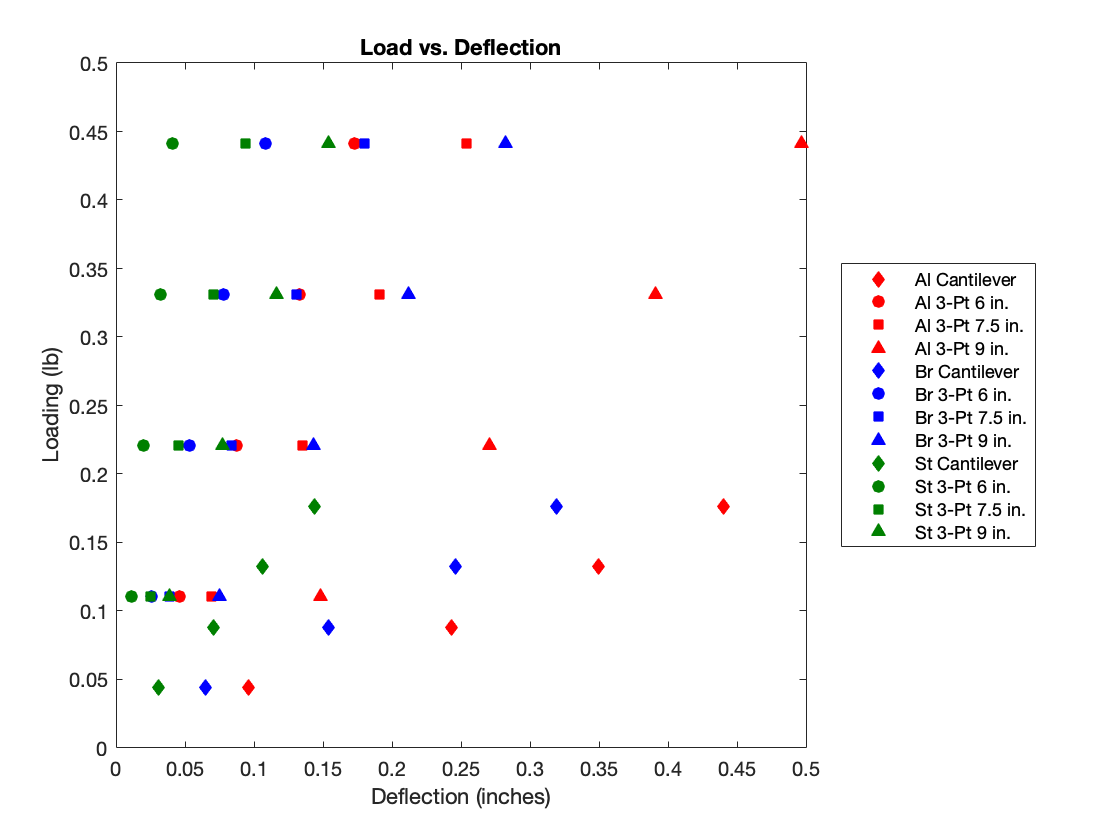


% Generate Plot 1 with all raw data
plot(cant_al, cant_load, 'd', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'r') % Aluminum
xlabel('Deflection (inches)')
ylabel('Loading (lb)')
title('Load vs. Deflection')
axis([0 0.5 0 0.5])
hold on
plot(tp_al_6, tp_load, 'o', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'r')
hold on
plot(tp_al_75, tp_load, 's', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'r')
hold on
plot(tp_al_9, tp_load, '^', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'r')
hold on
plot(cant_br, cant_load, 'd', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b') % Brass
hold on
plot(tp_br_6, tp_load, 'o', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b')
hold on
plot(tp_br_75, tp_load, 's', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b')
hold on
plot(tp_br_9, tp_load, '^', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b')
hold on
plot(cant_st, cant_load, 'd', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0]) % Steel
hold on
plot(tp_st_6, tp_load, 'o', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0])
hold on
plot(tp_st_75, tp_load, 's', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0])
hold on
plot(tp_st_9, tp_load, '^', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0])
legend('Al Cantilever', 'Al 3-Pt 6 in.', 'Al 3-Pt 7.5 in.', 'Al 3-Pt 9 in.', 'Br Cantilever', 'Br 3-Pt 6 in.', 'Br 3-Pt 7.5 in.', 'Br 3-Pt 9 in.', 'St Cantilever', 'St 3-Pt 6 in.', 'St 3-Pt 7.5 in.', 'St 3-Pt 9 in.', 'location', 'eastoutside')
hold off

## Section 3.3 Testing Lineararity of Response

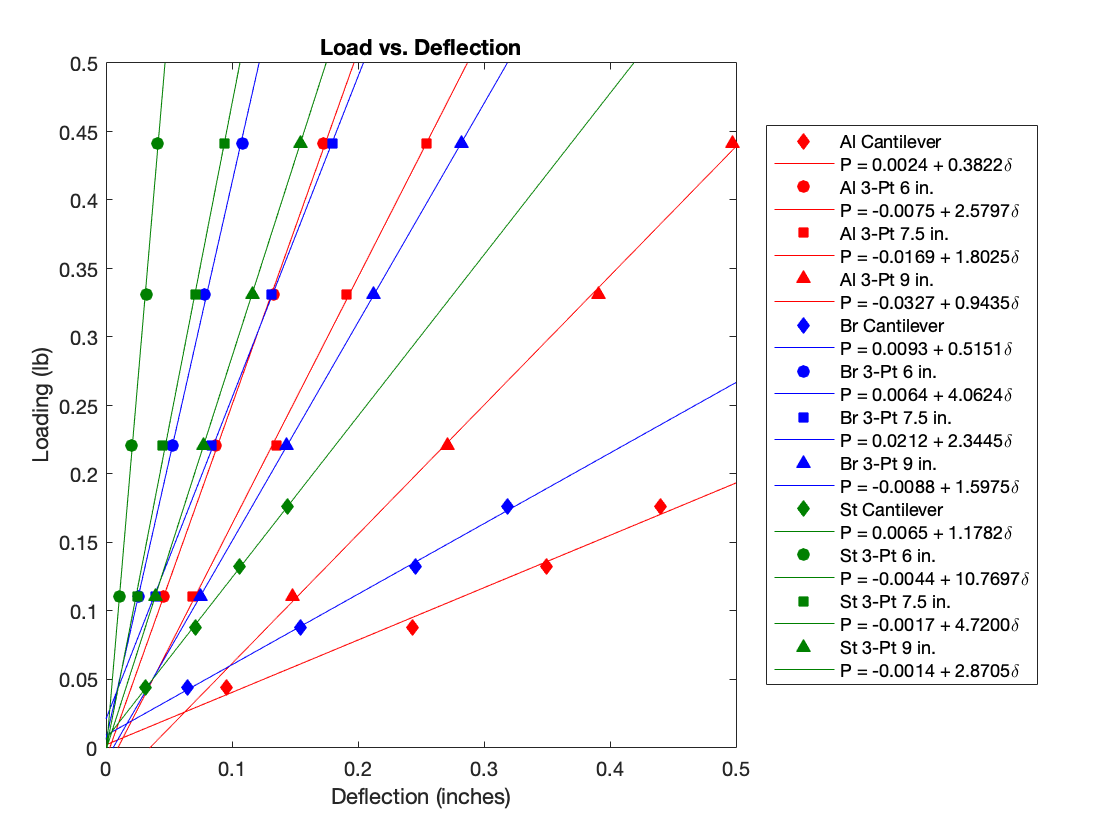


% Aluminum - generate 2x4 of P0 and k values for each trial
bls_al = ones(2,4);

bls_al(:,1) = regress(cant_load, [ones(4, 1) cant_al]); % cantilever
for i = 1:3
    bls_al(:,i+1) = regress(tp_load, [ones(4,1) al_tp_mat(:,i)]); % three pt bending
end
bls_al = flipud(bls_al); % makes k values row 1, P0 values row 2

% Brass - generate 2x4 of P0 and k values for each trial
bls_br = ones(2,4);

bls_br(:,1) = regress(cant_load, [ones(4, 1) cant_br]); % cantilever
for i = 1:3
    bls_br(:,i+1) = regress(tp_load, [ones(4,1) br_tp_mat(:,i)]); % three pt bending
end
bls_br = flipud(bls_br); % makes k values row 1, P0 values row 2

% Steel - generate 2x4 of P0 and k values for each trial
bls_st = ones(2,4);

bls_st(:,1) = regress(cant_load, [ones(4, 1) cant_st]); % cantilever
for i = 1:3
    bls_st(:,i+1) = regress(tp_load, [ones(4,1) st_tp_mat(:,i)]); % three pt bending
end
bls_st = flipud(bls_st); % makes k values row 1, P0 values row 2

% Generate Figure 2 Plot with trendlines
xtrend = linspace(0,0.5,100); % x trendline
trendeq = 'P = %.4f + %.4f%s';
plot(cant_al, cant_load, 'd', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'r') % Aluminum
xlabel('Deflection (inches)')
ylabel('Loading (lb)')
title('Load vs. Deflection')
axis([0 0.5 0 0.5])
hold on
plot(xtrend, polyval(bls_al(:,1),xtrend), 'r-')
hold on
plot(tp_al_6, tp_load, 'o', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'r')
hold on
plot(xtrend, polyval(bls_al(:,2),xtrend), 'r-')
hold on
plot(tp_al_75, tp_load, 's', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'r')
hold on
plot(xtrend, polyval(bls_al(:,3),xtrend), 'r-')
hold on
plot(tp_al_9, tp_load, '^', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'r')
hold on
plot(xtrend, polyval(bls_al(:,4),xtrend), 'r-')
hold on
plot(cant_br, cant_load, 'd', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b') % Brass
hold on
plot(xtrend, polyval(bls_br(:,1),xtrend), 'b-')
hold on
plot(tp_br_6, tp_load, 'o', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b')
hold on
plot(xtrend, polyval(bls_br(:,2),xtrend), 'b-')
hold on
plot(tp_br_75, tp_load, 's', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b')
hold on
plot(xtrend, polyval(bls_br(:,3),xtrend), 'b-')
hold on
plot(tp_br_9, tp_load, '^', 'MarkerFaceColor','b', 'MarkerEdgeColor', 'b')
hold on
plot(xtrend, polyval(bls_br(:,4),xtrend), 'b-')
hold on
plot(cant_st, cant_load, 'd', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0]) % Steel
hold on
plot(xtrend, polyval(bls_st(:,1),xtrend), '-', 'color', [0 0.5 0])
hold on
plot(tp_st_6, tp_load, 'o', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0])
hold on
plot(xtrend, polyval(bls_st(:,2),xtrend), '-', 'color', [0 0.5 0])
hold on
plot(tp_st_75, tp_load, 's', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0])
hold on
plot(xtrend, polyval(bls_st(:,3),xtrend), '-', 'color', [0 0.5 0])
hold on
plot(tp_st_9, tp_load, '^', 'MarkerFaceColor', [0 0.5 0], 'MarkerEdgeColor', [0 0.5 0])
hold on
plot(xtrend, polyval(bls_st(:,4),xtrend), '-','color', [0 0.5 0])
legend('Al Cantilever', sprintf(trendeq, bls_al(2,1), bls_al(1,1), '\delta'), 'Al 3-Pt 6 in.', sprintf(trendeq, bls_al(2,2), bls_al(1,2), '\delta'), ...
    'Al 3-Pt 7.5 in.', sprintf(trendeq, bls_al(2,3), bls_al(1,3), '\delta'), 'Al 3-Pt 9 in.', sprintf(trendeq, bls_al(2,4), bls_al(1,4), '\delta'), ...
    'Br Cantilever', sprintf(trendeq, bls_br(2,1), bls_br(1,1), '\delta'), 'Br 3-Pt 6 in.', sprintf(trendeq, bls_br(2,2), bls_br(1,2), '\delta'), ...
    'Br 3-Pt 7.5 in.', sprintf(trendeq, bls_br(2,3), bls_br(1,3), '\delta'), 'Br 3-Pt 9 in.', sprintf(trendeq, bls_br(2,4), bls_br(1,4), '\delta'), ...
    'St Cantilever', sprintf(trendeq, bls_st(2,1), bls_st(1,1), '\delta'), 'St 3-Pt 6 in.', sprintf(trendeq, bls_st(2,2), bls_st(1,2), '\delta'), ...
    'St 3-Pt 7.5 in.', sprintf(trendeq, bls_st(2,3), bls_st(1,3), '\delta'), 'St 3-Pt 9 in.', sprintf(trendeq, bls_st(2,4), bls_st(1,4), '\delta'), ...
    'location', 'eastoutside')
hold off


% Compute the Offset values - order is Cantilever, 6 in, 7.5 in, 9 in 3Pt
al_offset = [-bls_al(2,1)/bls_al(1,1) -bls_al(2,2)/bls_al(1,2) -bls_al(2,3)/bls_al(1,3) -bls_al(2,4)/bls_al(1,4)];
br_offset = [-bls_br(2,1)/bls_br(1,1) -bls_br(2,2)/bls_br(1,2) -bls_br(2,3)/bls_br(1,3) -bls_br(2,4)/bls_br(1,4)];
st_offset = [-bls_st(2,1)/bls_st(1,1) -bls_st(2,2)/bls_st(1,2) -bls_st(2,3)/bls_st(1,3) -bls_st(2,4)/bls_st(1,4)];


## Section 3.4 Testing Dependence of Bending Stiffness on Length and Boundary Conditions


% Input E, L, and I parameters
d = 0.125; % diameter in inches
L_cant = 9; % length of cantilever beam in inches
L_3pt6 = 12; % length of 3pt trial measured at 6 inch mark
L_3pt75 = 15; % length of 3pt trial measured at 7.5 inch mark
L_3pt9 = 18; % length of 3pt trial measured at 9 inch mark
E_al = 10200000; % Young's Modulus in lbf/in^2
E_br = 14100000; % Young's Modulus in lbf/in^2
E_st = 28000000; % Young's Modulus in lbf/in^2
I = pi*(d^4)/64; % inches^4

% Compute k_bending(tilda)
al_kb = [bls_al(1,1)/3 bls_al(1,2)/48 bls_al(1,3)/48 bls_al(1,4)/48];
br_kb = [bls_br(1,1)/3 bls_br(1,2)/48 bls_br(1,3)/48 bls_br(1,4)/48];
st_kb = [bls_st(1,1)/3 bls_st(1,2)/48 bls_st(1,3)/48 bls_st(1,4)/48];

% Calculate theoretical Euler-Bernoulli values
al_eb = (1/(E_al*I))^(1/3);
br_eb = (1/(E_br*I))^(1/3);
st_eb = (1/(E_st*I))^(1/3);

% Calculate actual Euler-Bernoulli values using same order as offset
al_eb_actual = [((1/al_kb(1))^(1/3))*(1/L_cant) ((1/al_kb(2))^(1/3))*(1/L_3pt6) ((1/al_kb(3))^(1/3))*(1/L_3pt75) ((1/al_kb(4))^(1/3))*(1/L_3pt9)];
br_eb_actual = [((1/br_kb(1))^(1/3))*(1/L_cant) ((1/br_kb(2))^(1/3))*(1/L_3pt6) ((1/br_kb(3))^(1/3))*(1/L_3pt75) ((1/br_kb(4))^(1/3))*(1/L_3pt9)];
st_eb_actual = [((1/st_kb(1))^(1/3))*(1/L_cant) ((1/st_kb(2))^(1/3))*(1/L_3pt6) ((1/st_kb(3))^(1/3))*(1/L_3pt75) ((1/st_kb(4))^(1/3))*(1/L_3pt9)];

% Calculate percent difference from theoretical using same order as offset
al_perdiff = ones(1,4);
for i = 1:length(al_perdiff)
    al_perdiff(1,i) = ((al_eb_actual(1,i) - al_eb)/al_eb)*100;
end

br_perdiff = ones(1,4);
for i = 1:length(br_perdiff)
    br_perdiff(1,i) = ((br_eb_actual(1,i) - br_eb)/br_eb)*100;
end

st_perdiff = ones(1,4);
for i = 1:length(st_perdiff)
    st_perdiff(1,i) = ((st_eb_actual(1,i) - st_eb)/st_eb)*100;
end

% Calculate average with percent difference underneath - order is Al, Br, St
Ave_eb = [mean(al_eb_actual) mean(br_eb_actual) mean(st_eb_actual); ((mean(al_eb_actual) - al_eb)/al_eb)*100 ((mean(br_eb_actual) - br_eb)/br_eb)*100 ((mean(st_eb_actual) - st_eb)/st_eb)*100];


## Section 3.5 Testing Predictions of the Deflection Curve for Three-Point Bending

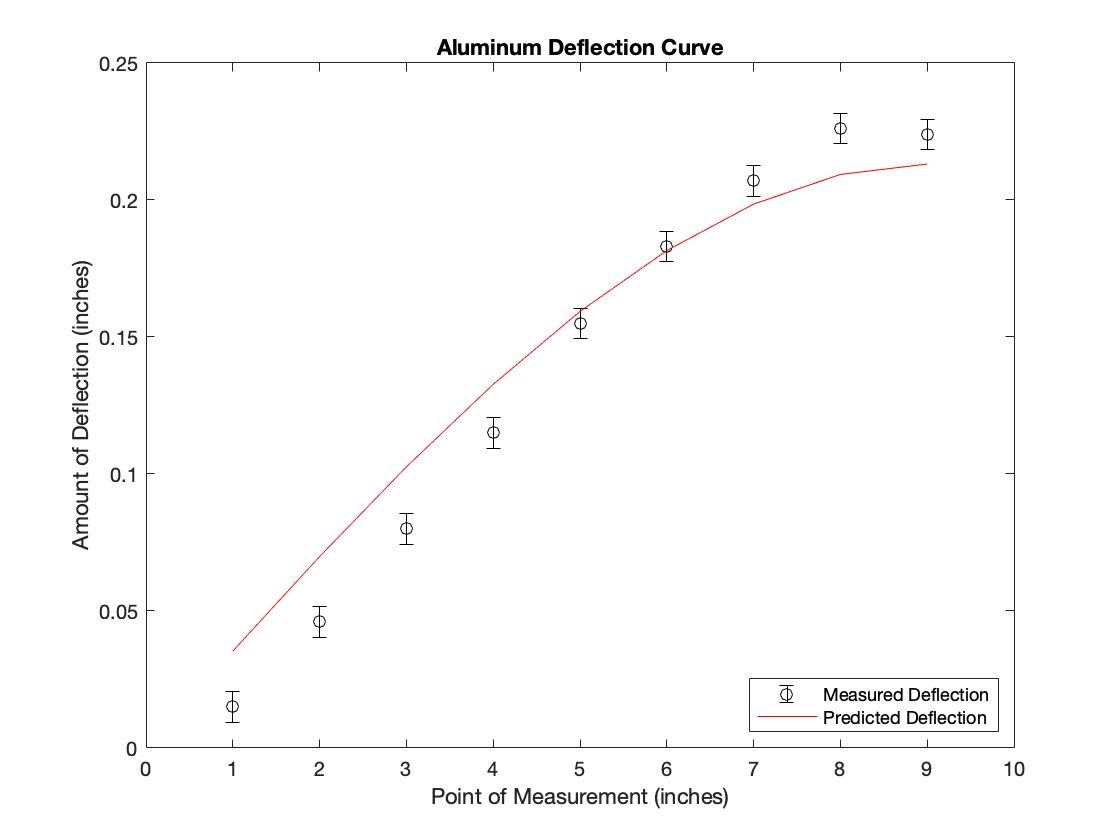

% Calculate deflection due to load
al_delta_j = def_al_200 - def_al_100;
br_delta_j = def_br_200 - def_br_100;
st_delta_j = def_st_200 - def_st_100;

% Calculate maximum deflection of beam
L = L_3pt9;
x = [1:length(def_len)];

v = ones(1,length(x));
for i = 1:length(v)
    v(i) = (1/(L^3))*((3*L^2 - 4*x(i)^2)*x(i) +4*((abs(x(i)-L/2))^3 + (x(i) - L/2)^3));
end
v = v';
al_delta_max = sum(v'*al_delta_j)/sum(v'*v);
br_delta_max = sum(v'*br_delta_j)/sum(v'*v);
st_delta_max = sum(v'*st_delta_j)/sum(v'*v);

% Calculate delta_delta & error bars & plot
g = 5/32; % gauge width in inches

% Aluminum
al_theta_max = 3 * al_delta_max/L;
al_delta_delta = al_theta_max * g; % magnitude of error
al_error = ones(9,1)*al_delta_delta;

figure(3), errorbar(x, al_delta_j, al_error, al_error, 'ko') % plot data
hold('on')
figure(3), plot(x, al_delta_max*v, 'red') % add theoretical curve
title('Aluminum Deflection Curve')
xlabel('Point of Measurement (inches)')
ylabel('Amount of Deflection (inches)')
axis([0 10 0 0.25])
legend('Measured Deflection', 'Predicted Deflection', 'Location', 'southeast')
hold('off')

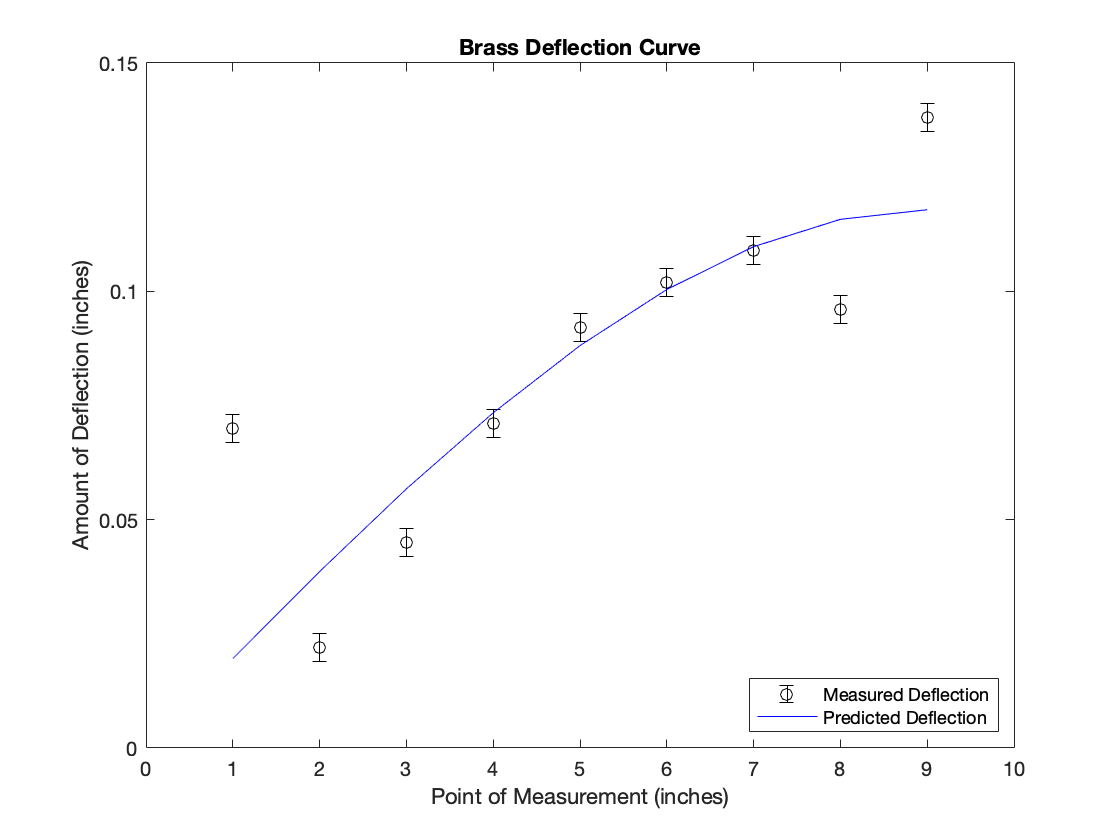



% Brass
br_theta_max = 3 * br_delta_max/L;
br_delta_delta = br_theta_max * g; % magnitude of error
br_error = ones(9,1)*br_delta_delta;

figure(3), errorbar(x, br_delta_j, br_error, br_error, 'ko') % plot data
hold('on')
figure(3), plot(x, br_delta_max*v, 'blue') % add theoretical curve
title('Brass Deflection Curve')
xlabel('Point of Measurement (inches)')
ylabel('Amount of Deflection (inches)')
axis([0 10 0 0.15])
legend('Measured Deflection', 'Predicted Deflection', 'Location', 'southeast')
hold('off')

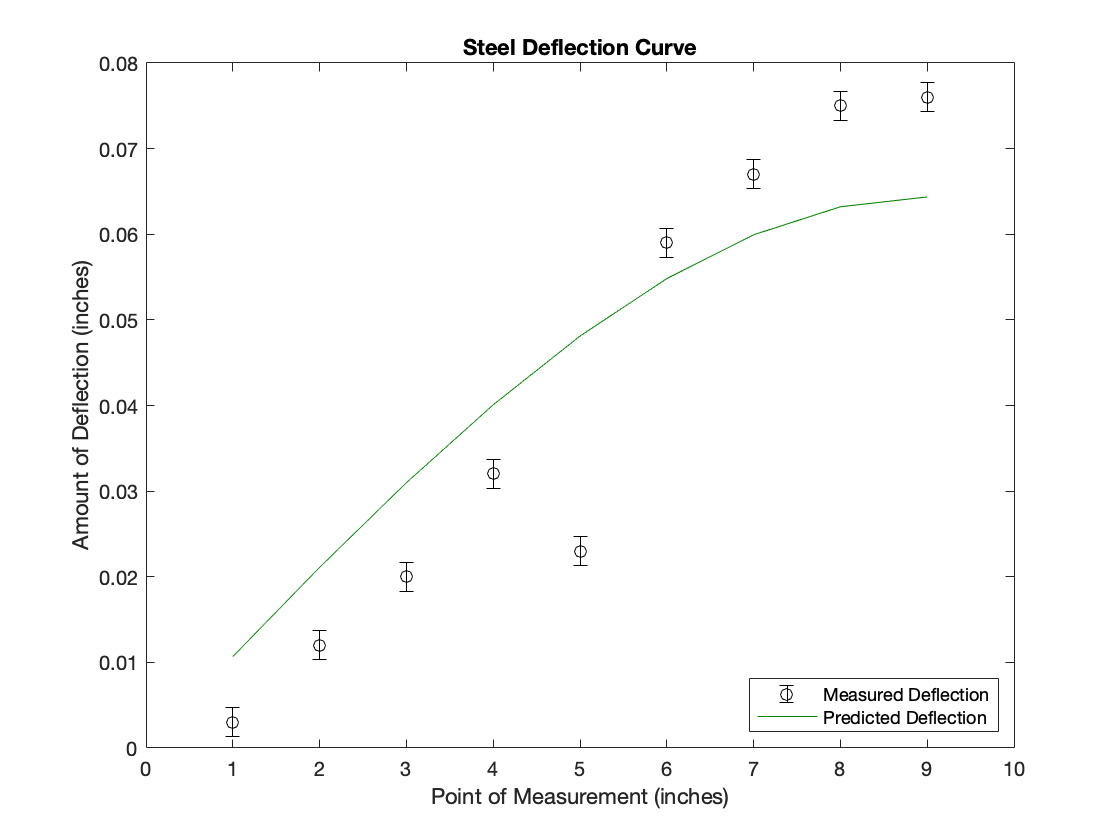


% Steel
st_theta_max = 3 * st_delta_max/L;
st_delta_delta = st_theta_max * g; % magnitude of error
st_error = ones(9,1)*st_delta_delta;

figure(3), errorbar(x, st_delta_j, st_error, st_error, 'ko') % plot data
hold('on')
figure(3), plot(x, st_delta_max*v, 'color', [0 0.5 0]) % add theoretical curve
title('Steel Deflection Curve')
xlabel('Point of Measurement (inches)')
ylabel('Amount of Deflection (inches)')
axis([0 10 0 0.08])
legend('Measured Deflection', 'Predicted Deflection', 'Location', 'southeast')
hold('off')